clc;
clear all;
load('datacircle.mat');
%least square
C=[2*x,2*y,ones(100,1)];
z=x.^2+y.^2;
theta=C\z;
a=theta(1)

a = -0.9744

b=theta(2)

b = 1.9784

R=sqrt(theta(3)+a^2+b^2)

R = 3.0451



% using fitlm
model=fitlm(C,z);

model 

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)     4.4094      0.23915     18.437    2.6264e-33
    x1             -0.9744     0.038198    -25.509    1.5024e-44
    x2              1.9784     0.038663      51.17      1.78e-71
    x3                   0            0        NaN           NaN

Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 1.65
R-squared: 0.971,  Adjusted R-Squared: 0.97
F-statistic vs. constant model: 1.63e+03, p-value = 2.44e-75


anovaOFmodel=anova(model,'summary')

anovaOFmodel = 3×5 table
                SumSq     DF    MeanSq     F        pValue  
                ______    __    ______    ____    __________
    Total       9176.4    99    92.691                      
    Model       8910.7     2    4455.4    1627    2.4415e-75
    Residual    265.63    97    2.7384                      


model.Coefficients

ans = 4×4 table
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)     4.4094      0.23915     18.437    2.6264e-33
    x1             -0.9744     0.038198    -25.509    1.5024e-44
    x2              1.9784     0.038663      51.17      1.78e-71
    x3                   0            0        NaN           NaN


%model.Diagnostics

intercept=model.Coefficients.Estimate(1,1);
ap=model.Coefficients.Estimate(2,1)

ap = -0.9744

bp=model.Coefficients.Estimate(3,1)

bp = 1.9784

Rp=sqrt(intercept+ap^2+bp^2)

Rp = 3.0451

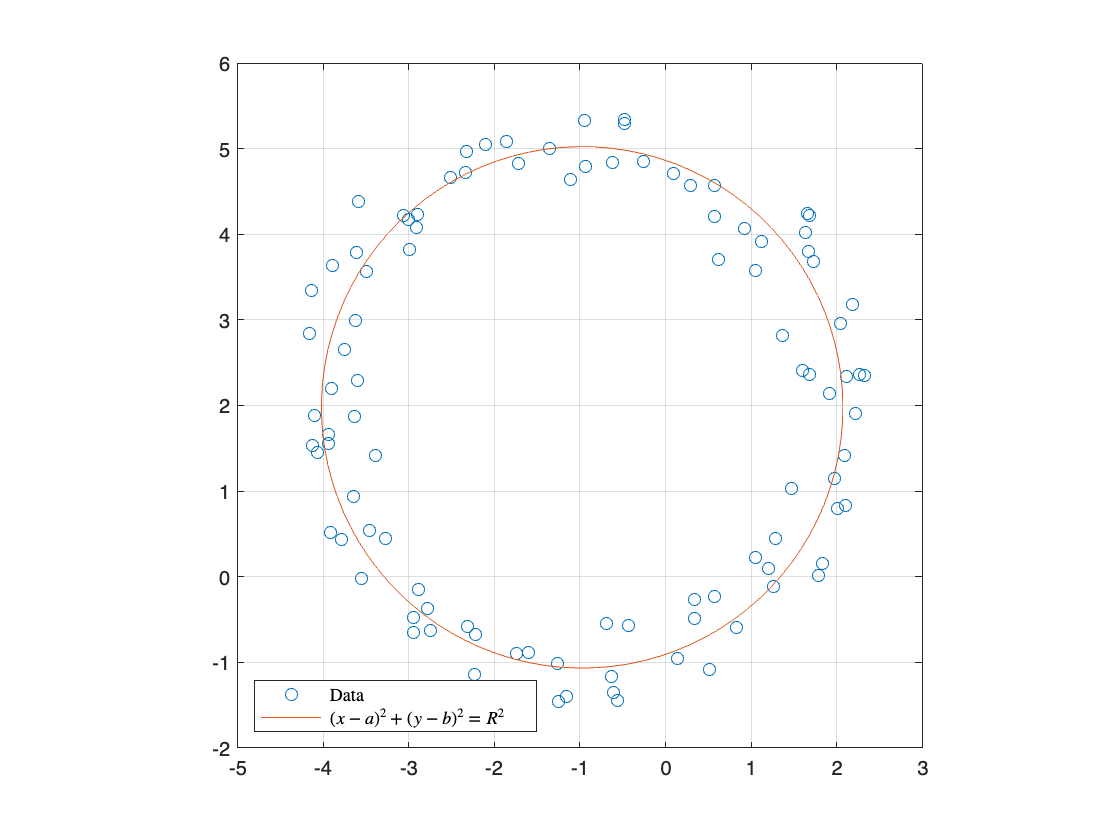


%plot
t=linspace(0,2*pi,100);
plot(x,y,"o",a+R*cos(t),b+R*sin(t),"-")
xlim([-5 3])
ylim([-2 6])
grid on
daspect([1 1 1])

legend({'Data','$(x-a)^2+(y-b)^2=R^2$'},'interpreter','latex','Location','southwest')

saveas(gcf,'Figures/FigureCircle.pdf')
set(gcf,'Units','centimeters');
screenposition = get(gcf,'Position');
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',[screenposition(3:4)]);
print -dpdf -painters Figures/FigureCircle

cleanfigure;
matlab2tikz('Figures/FigureCircle.tex','width','\figwidth','height','\figheight','showInfo',false);